# Modelo Goodwin

Luis Alejandro Baena Marín - Juan Camilo Bermúdez Colorado

## 1. Introducción

En el estudio de la dinámica macroeconómica, la interacción entre el empleo, la participación salarial y el crecimiento económico ha sido un área clave de interés. Uno de los modelos más conocidos que trata de capturar estas relaciones es el modelo de crecimiento cíclico de Richard Goodwin, propuesto en 1967. Este modelo utiliza ecuaciones diferenciales no lineales para describir la interacción entre la participación salarial ($\omega$) y la tasa de empleo ($\lambda$) a lo largo del tiempo, dentro de una economía capitalista.

El modelo de Goodwin se basa en principios marxistas, donde los ciclos económicos son explicados como el resultado de la lucha de clases entre los trabajadores, que buscan maximizar los salarios, y los capitalistas, que buscan maximizar las ganancias. Las ecuaciones fundamentales del modelo representan la evolución de la participación salarial y la tasa de empleo en función de variables como la productividad, la depreciación del capital y el crecimiento poblacional.

Modelo de Goodwin:

        
$$\left\{
\begin{array}{ll}
\dot{\omega} = \omega \left( \frac{\phi_1}{(1 - \lambda)^2} - \phi_0 - \alpha \right) \\
\dot{\lambda} = \lambda \left( \frac{1 - \omega}{\nu} - \alpha - \beta - \delta \right)
\end{array}
\right. \\

Y_{\text{output}}(t) = Y_0 \cdot \frac{\lambda(t)}{\lambda(0)} \cdot \exp\left((\alpha + \beta) \cdot t\right)
\end{equation}
$$


donde:

        
$$\omega:  \text{participación salarial} \\
\lambda: \text{tasa de empleo} \\
Y_{output}(t): \text{es la salida económica del sistema en el tiempo t} \\

\textbf{Definiciones de Parámetros:} \\
\bullet \ \nu : \text{Tasa de capital a salida.} \\
\bullet \ \alpha : \text{Tasa de crecimiento de productividad.} \\
\bullet \ \beta : \text{Tasa de crecimiento de población.} \\
\bullet \ \delta : \text{Tasa de depreciación.} \\
\bullet \ \phi_0 \text{ y } \phi_1 : \text{Parámetros de la curva de Phillips.} \\
\bullet \ Y_0 : \text{Producto Interno Bruto (GDP) inicial} \\

\bullet \ t : \text{es el tiempo de simulación.}
$$


Este trabajo tiene como objetivo modelar y simular el sistema dinámico no lineal del modelo de Goodwin utilizando Simulink, y analizar su comportamiento bajo diferentes condiciones de entrada. A través de esta simulación, se explorará cómo el sistema responde a perturbaciones en las condiciones iniciales y cómo los cambios en los parámetros económicos afectan la dinámica del empleo y los salarios. Además, se implementarán tres tipos de entradas (escalón, sinusoidal, pulso) para estudiar la respuesta del sistema, y se realizarán modificaciones en dos parámetros clave del modelo para evaluar cómo estos cambios alteran las características de la respuesta temporal.

La simulación del modelo de Goodwin permite una comprensión más profunda de la naturaleza cíclica del crecimiento económico y ofrece una herramienta para examinar los efectos de las políticas económicas en la estabilidad del empleo y los salarios.

Para entender mejor el comportamiento del modelo, es importante tener en cuenta el significado intuitivo de los parámetros utilizados:

- $\nu$**: Tasa de capital a salida: **Este parámetro representa la proporción de la producción que se destina al capital. Un valor más alto indica que se requiere una mayor inversión de capital para generar una unidad de salida económica. En términos simples, refleja cuán intensiva en capital es la economía.

- $\alpha$**: Tasa de crecimiento de productividad: **Este parámetro mide cómo la productividad, es decir, la cantidad de output por unidad de trabajo, crece a lo largo del tiempo. Un aumento en la productividad puede traducirse en un mayor output económico sin necesidad de aumentar el empleo. Intuitivamente, es una medida de progreso técnico y eficiencia en la producción.

- $\beta$**: Tasa de crecimiento de población: **Este parámetro describe la velocidad a la que crece la población trabajadora. A mayor tasa de crecimiento de la población, más rápido aumentará la oferta de trabajadores en la economía, lo que puede ejercer presión sobre los salarios y el empleo.

- $\delta$**: Tasa de depreciación: **La tasa de depreciación indica la disminución en el valor del capital con el tiempo, debido al desgaste o la obsolescencia. Un valor alto sugiere que el capital en la economía se deteriora rápidamente, lo que podría requerir una mayor inversión continua para mantener el mismo nivel de producción.

- $\phi_0 \;y\;\phi_1$**: Parámetros de la curva de Phillips: **Estos parámetros representan la relación entre la inflación salarial y el desempleo, conocida como la curva de Phillips. El parámetro $\phi_0$ captura el nivel base de presión salarial que existe en la economía, mientras que $\phi_1$ mide cómo la tasa de empleo afecta la presión sobre los salarios. En el modelo de Goodwin, estas variables influyen directamente en la evolución de la participación salarial en función de la tasa de empleo.

- $Y_0$**: Producto Interno Bruto (GDP) inicial:** Este parámetro representa el valor del GDP al inicio de la simulación. Intuitivamente es una referencia que captura el nivel de producción económica de un país o región en un momento inicial del tiempo. A medida que el modelo evoluciona, el GDP cambiará en función de la tasa de empleo y los factores de crecimiento, pero $Y_0$ establece la base sobre la cual se medirán esos cambios.

- $Y_{\textrm{output}} \left(t\right)$**:** Es el Producto Interno Bruto (GDP) en el tiempo t. Intuitivamente, esta ecuación muestra cómo el GDP cambia a lo largo del tiempo según la tasa de empleo $\lambda \left(t\right)$ y el crecimiento combinado de la productividad $\alpha$ y la población $\beta$. Si la tasa de empleo aumenta y los trabajadores son más productivos, el GDP crecerá de forma exponencial. $Y_0$ es el GDP inicial, y $\lambda_0$ es la tasa de empleo inicial.

En el modelo de Goodwin, se hacen dos suposiciones clave. La primera es que los salarios reales cambian en función de la tasa de empleo. A medida que aumenta el empleo, los salarios también suben debido a la mayor demanda de mano de obra, lo que refleja la idea de la curva de Phillips, donde hay una relación entre desempleo y crecimiento salarial. La segunda suposición es la ley de Say, que sostiene que todos los salarios se consumen y todas las ganancias se reinvierten en capital. Esto implica que el capital en la economía crece según las ganancias que quedan después de pagar los salarios y restando la depreciación.

En el modelo de Goodwin, bajo la condición  $ \( \nu - \alpha - \beta - \delta > 0 \)

$, hay el punto de equilibrio trivial  $\( (\omega_0, \lambda_0) = (0, 0) \)
$ se comporta como un punto de silla. Esto significa que es un equilibrio inestable, aunque las variables como la participación salarial y la tasa de empleo pueden acercarse a este punto, el sistema tiende a alejarse de él en algunas direcciones.

Por otro lado, el punto de equilibrio no trivial $\( (\omega_1, \lambda_1) = \left( 1 - \nu(\alpha + \beta + \delta), \frac{\alpha + \phi_0}{\phi_1} \right) \)$ es no hiperbólico, lo que significa que el comportamiento del sistema en torno a este equilibrio es más complejo, ya que uno de los autovalores del sistema tiene una parte real igual a cero. En lugar de converger o divergir de manera clara y exponencial, las trayectorias del sistema alrededor de este equilibrio tienden a ser cíclicas o periódicas. Es decir, las soluciones del sistema describen órbitas periódicas centradas en $\( (\omega_1, \lambda_1) \)$, lo que refleja el comportamiento cíclico del empleo y los salarios en el modelo.

Ecuaciones de estado:

El modelo de Goodwin se puede representar mediante un sistema de ecuaciones diferenciales que describen la dinámica de la participación salarial $\omega$ y la tasa de empleo $\lambda$. En el contexto de este modelo, las variables $\omega$ y $\lambda$ se han renombrado como $x_1$ y $x_2$, respectivamente, para simplificar la notación. Las ecuaciones de estado son las siguientes:


$$\left\{
\begin{array}{ll}
\dot{x}_1 = x_1 \left( \frac{\phi_1}{(1 - x_2)^2} - \phi_0 - \alpha \right) \\ 
\dot{x}_2 = x_2 \left( \frac{1 - x_1}{\nu} - \alpha - \beta - \delta \right) + u_{input}
\end{array}
\right. 
 \\

Y_{\text{output}}(t) = Y_0 \cdot \frac{x_2(t)}{x_2(0)} \cdot \exp\left((\alpha + \beta) \cdot t\right)
$$


**Entrada externa o estímulo**: Se ha añadido un término adicional $u_{\textrm{input}} \left(t\right)$, que representa cualquier intervención externa que influye directamente en la tasa de empleo $\lambda$. Este estímulo puede interpretarse como una política económica (como una política fiscal expansiva, subsidios, o cambios en las condiciones del mercado laboral) que afecta el nivel de empleo. Al incorporarla, el modelo permite simular cómo reacciona la economía ante perturbaciones externas o estímulos que no se encuentran dentro de la dinámica interna natural del sistema. Esto mejora la representatividad del modelo, al reflejar cómo las economías reales a menudo están influenciadas por intervenciones externas.

Esta entrada se integra en la ecuación de la tasa de empleo $x_{2\;}$($\lambda$), donde su derivada temporal describe el cambio en la tasa de empleo respecto al tiempo. La tasa de empleo se define como una proporción y, por tanto, es adimensional. Sin embargo, al considerar su derivada con respecto al tiempo, se obtiene una tasa de cambio, la cual tiene dimensiones de ${\left\lbrack T\right\rbrack }^{-1}$, es decir, unidades inversas de tiempo. Por lo tanto, para que $u_{\textrm{input}} \left(t\right)$ se integre correctamente en la ecuación, debe tener las mismas unidades de ${\left\lbrack T\right\rbrack }^{-1}$.

De este modelo, podemos sacar varias hipótesis:

- **Hipótesis sobre la respuesta del modelo ante diferentes tipos de entrada**: Se prevé que la aplicación de distintos tipos de perturbaciones (escalón, seno y pulso) generará cambios significativos en la dinámica del sistema, impactando tanto la tasa de empleo ($\lambda$) como la participación salarial ($\omega$). Las entradas escalón y sinusoidal deberían inducir ajustes más progresivos y predecibles en la economía. En contraste, un pulso, al ser un cambio breve en un intervalo específico de tiempo, se espera que produzca un efecto transitorio en las variables económicas, con una respuesta limitada en duración, pero significativa en magnitud durante ese corto periodo. Se espera que la naturaleza de la entrada afecte tanto la velocidad de ajuste como la amplitud de las oscilaciones cíclicas de la economía.

- **Hipótesis sobre la relación entre la participación salarial y la tasa de empleo**: Se plantea que un aumento en la participación salarial ($\omega$) estará positivamente correlacionado con un incremento en la tasa de empleo ($\lambda$). Este razonamiento se apoya en la lógica de que una mayor proporción salarial mejora la capacidad de los trabajadores para negociar mejores condiciones laborales, lo que aumenta su participación en el mercado de trabajo y eleva la demanda agregada. Esta mayor demanda podría incentivar a las empresas a contratar más mano de obra, contribuyendo a un aumento en la tasa de empleo.

- **Hipótesis sobre el efecto de la productividad**: Se espera que una mayor tasa de crecimiento de la productividad ($\alpha$) resulte en un aumento en la tasa de empleo ($\lambda$). Esto se debe a que una mayor productividad incrementa el producto total de la economía, permitiendo un mayor nivel de output por trabajador. Esto no solo mejora la rentabilidad de las empresas, sino que también fomenta la inversión en nuevas tecnologías y empleos, generando más oportunidades laborales y, potencialmente, un crecimiento en la proporción salarial.

- **Hipótesis sobre la depreciación del capital**: Se prevé que un incremento en la tasa de depreciación del capital ($\delta$) tendrá un impacto negativo en la tasa de empleo ($\lambda$). A medida que el capital físico se deprecia más rápidamente, las empresas enfrentarán mayores costos de reposición, lo que puede frenar la inversión productiva y limitar su capacidad para expandir el empleo. A largo plazo, esto podría traducirse en una contracción del crecimiento económico y en una menor participación salarial ($\omega$).

## 2. Métodos

Para analizar el comportamiento del modelo de Goodwin, se realizaron una serie de simulaciones utilizando Matlab y Simulink, teniendo en cuenta el artículo de referencia elegido. En particular, se utilizó Simulink para construir el modelo dinámico, utilizando integradores y ecuaciones diferenciales que definen la evolución de las variables clave: la participación salarial ($\omega$) y la tasa de empleo ($\lambda$).

Cada simulación se enfocó en analizar la respuesta del sistema bajo diferentes tipos de señales de entrada: escalón, seno y pulso, que fueron implementadas como perturbaciones controladas a través del parámetro $u_{\textrm{input}} \left(t\right)$. Estas perturbaciones simulan factores externos que afectan la dinámica económica, como políticas fiscales o eventos económicos inesperados.

**Pasos para la realización de las simulaciones:**

- **Implementación del modelo**: Se implementaron las ecuaciones diferenciales del modelo que relacionan la proporción salarial y la tasa de empleo, junto con la ecuación para calcular la salida económica $Y_{\textrm{output}} \left(t\right)$. Además, se creó una máscara para permitir la configuración fácil de los parámetros del sistema.

- **Configuración de parámetros**: Se establecieron los valores del artículo de referencia para los parámetros del modelo como la tasa de crecimiento de la productividad ($\alpha$), tasa de crecimiento de la población ($\beta$), tasa de depreciación del capital ($\delta$), y parámetros de la curva de Phillips ($\phi_0 \;y\;\phi_1$). Los resultados obtenidos se compararon con la literatura para verificar la consistencia del modelo.

- **Simulación con diferentes entradas**: Se realizaron pruebas variando el tipo de señal de entrada $u_{\textrm{input}} \left(t\right)$ para observar la evolución temporal de $\omega$, $\lambda$ y $Y_{\textrm{output}} \left(t\right)$ ante perturbaciones. Las entradas utilizadas fueron: **Escalón**: Un cambio brusco en $u_{\textrm{input}} \left(t\right)$ en un tiempo determinado; **Seno**: Una perturbación oscilante; **Pulso**: Una señal en un pequeño rango especifico.

- **Simulación cambiando parámetros**: Adicionalmente, se realizaron simulaciones variando dos parámetros específicos: $\alpha$ (Tasa de crecimiento de productividad) y $\delta$ (Tasa de depreciación), con el fin de observar su impacto en el comportamiento del sistema.

- **Análisis de resultados**: Los resultados fueron representados gráficamente para estudiar la respuesta dinámica de la proporción salarial, la tasa de empleo y la producción bajo cada escenario de entrada. Esto permitió identificar cómo diferentes perturbaciones afectan el comportamiento económico y qué implicaciones tiene en el equilibrio del modelo.

## 3. Resultados

### 3.1. Modelo en Simulink

### 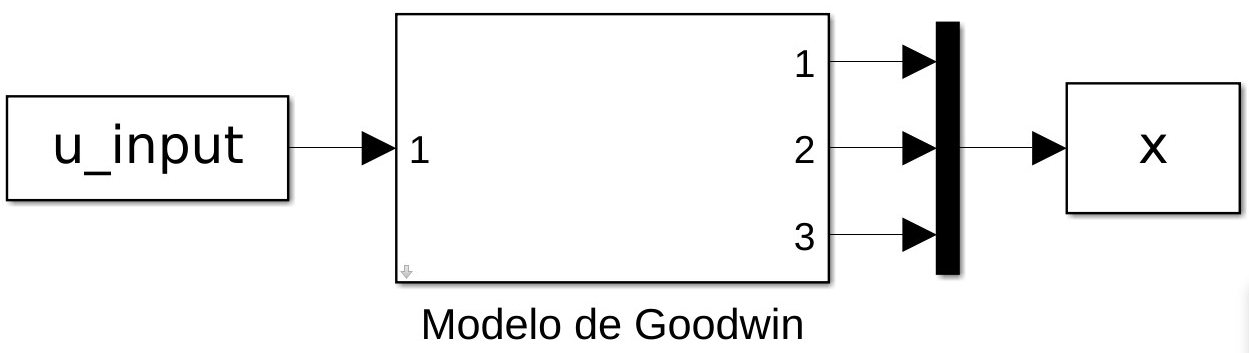

Subsistema Modelo de Goodwin:

### 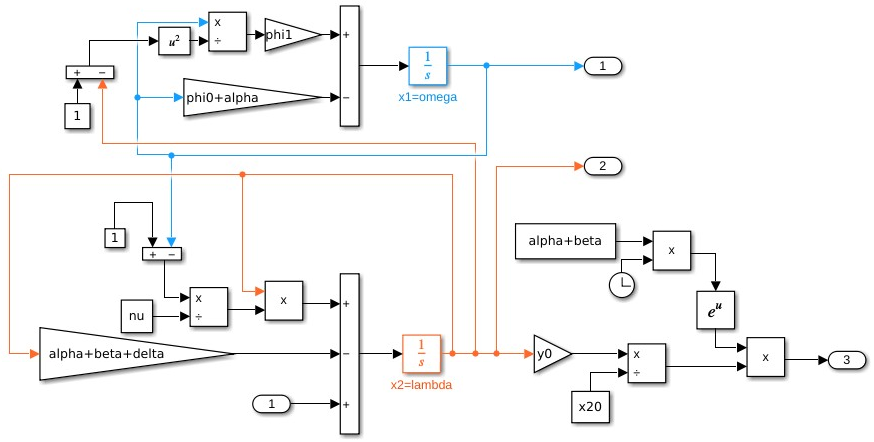

### **3.2. Simulación y verificación**

nu = 3;              % razón capital-producto
alpha = 0.025;       % tasa de crecimiento de la productividad
beta = 0.02;         % tasa de crecimiento de la población
delta = 0.01;        % tasa de depreciación
phi0 = 0.04/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega
x20 = 0.9; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial

tmax = 100;
t = linspace(0, tmax, 1000)'; % Vector de tiempo con 1000 puntos entre 0 y tmax
u = zeros(size(t)); % Señal constante igual a 0 para todos los puntos de tiempo

% Crear la señal de entrada para "From Workspace"
u_input = [t u];

% Ejecutar la simulación
sim('goodwin')

fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2); % inversa de la curva de Phillips
omega_bar =  1-nu*(alpha+beta+delta)           % equilibrio proporción salarial

omega_bar = 0.8350

lambda_bar = fun_Phi_inv(alpha)                % equilibrio razón de empleo

lambda_bar = 0.9686

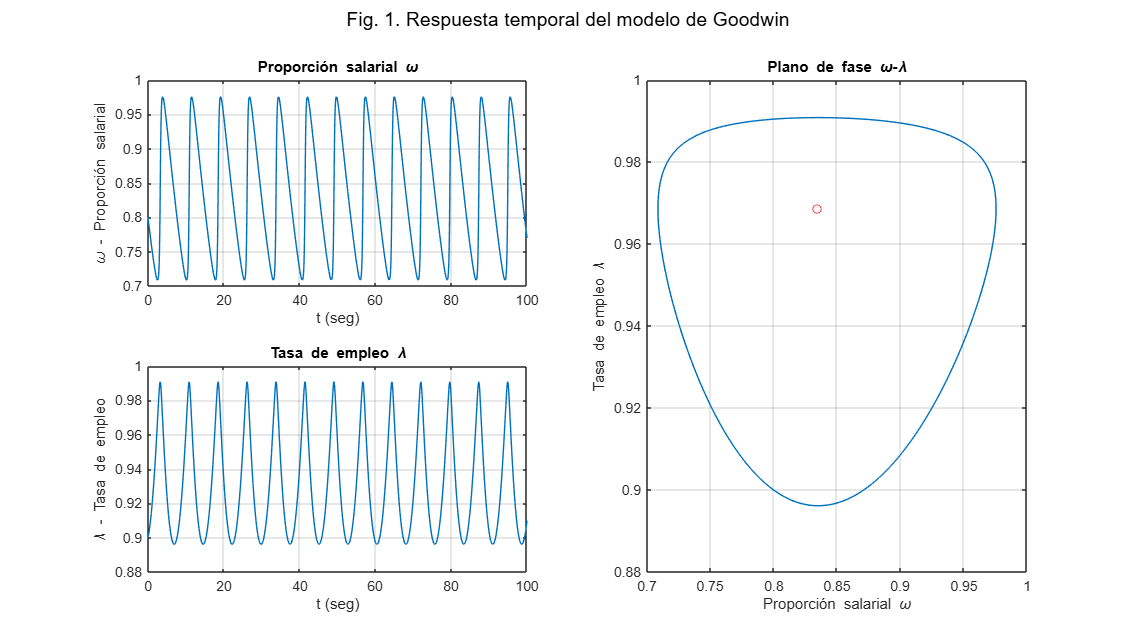

% Extraer datos y graficar resultados
t = x.time;
x1 = x.signals.values(:,1); % w = x1 (Proporción salarial)
x2 = x.signals.values(:,2); % lambda = x2 (Razón de empleo)
x3 = x.signals.values(:,3); % Y_output = x3 (Producto Interno Bruto (GDP))

figure('Units','normalized','Position',[0 0 1 1])
sgtitle({'Fig. 1. Respuesta temporal del modelo de Goodwin';''})

% Gráfica de Proporción Salarial
subplot(2,2,1)
plot(t,x1)
xlabel('t (seg)'), ylabel('\omega - Proporción salarial'), title('Proporción salarial \omega'), grid

% Gráfica de Tasa de Empleo
subplot(2,2,3)
plot(t,x2)
xlabel('t (seg)'), ylabel('\lambda - Tasa de empleo'), title('Tasa de empleo \lambda'), grid

% Diagrama de fase
subplot(2,2,[2,4])
plot(x1,x2); hold on;
plot(omega_bar, lambda_bar, 'ro')
xlabel('Proporción salarial \omega'), ylabel('Tasa de empleo \lambda'), title('Plano de fase \omega-\lambda'), grid

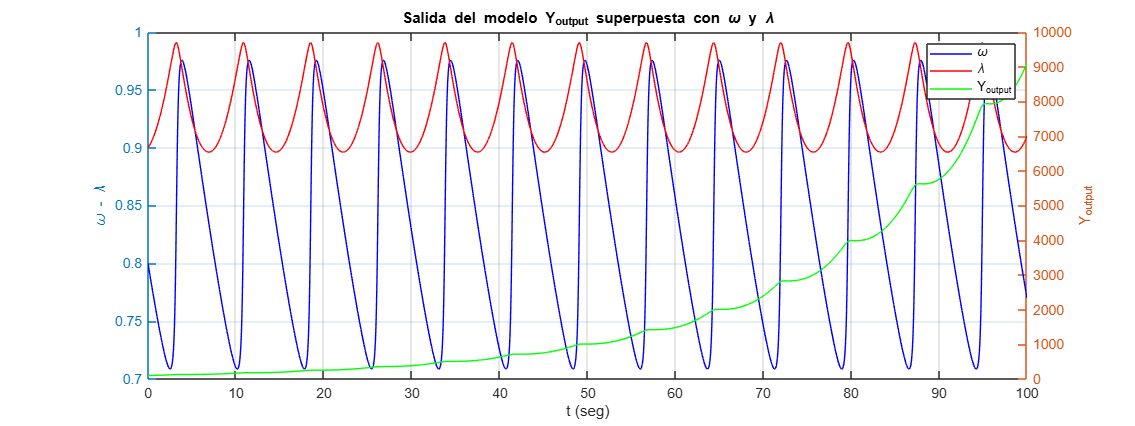

% Crear la figura
figure('Units','normalized','Position',[0 0 0.9 0.6])

% Eje izquierdo para x1 y x2
yyaxis left
plot(t, x1, '-b', 'DisplayName', '\omega'); % Gráfica de x1
hold on
plot(t, x2, '-r', 'DisplayName', '\lambda'); % Gráfica de x2
xlabel('t (seg)');
ylabel('\omega - \lambda');
title('Salida del modelo Y_{output} superpuesta con \omega y \lambda');
grid on
legend('show');

% Eje derecho para x3
yyaxis right
plot(t, x3, '-g', 'DisplayName', 'Y_{output}'); % Gráfica de x3
ylabel('Y_{output}');

Resultados del artículo de referencia:

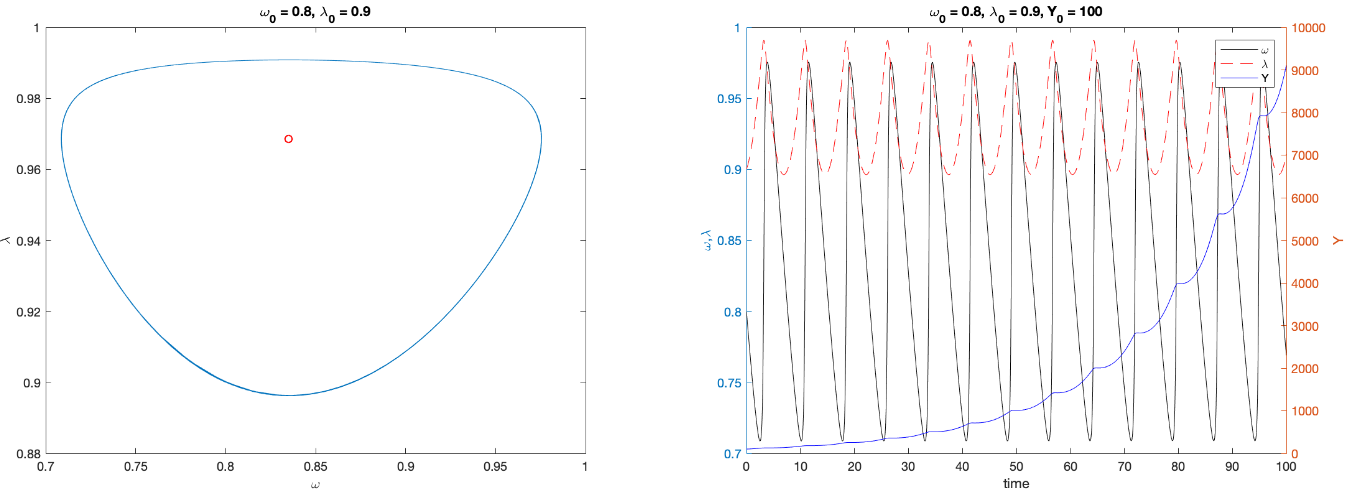

### 3.3. Simulación con entrada tipo escalón

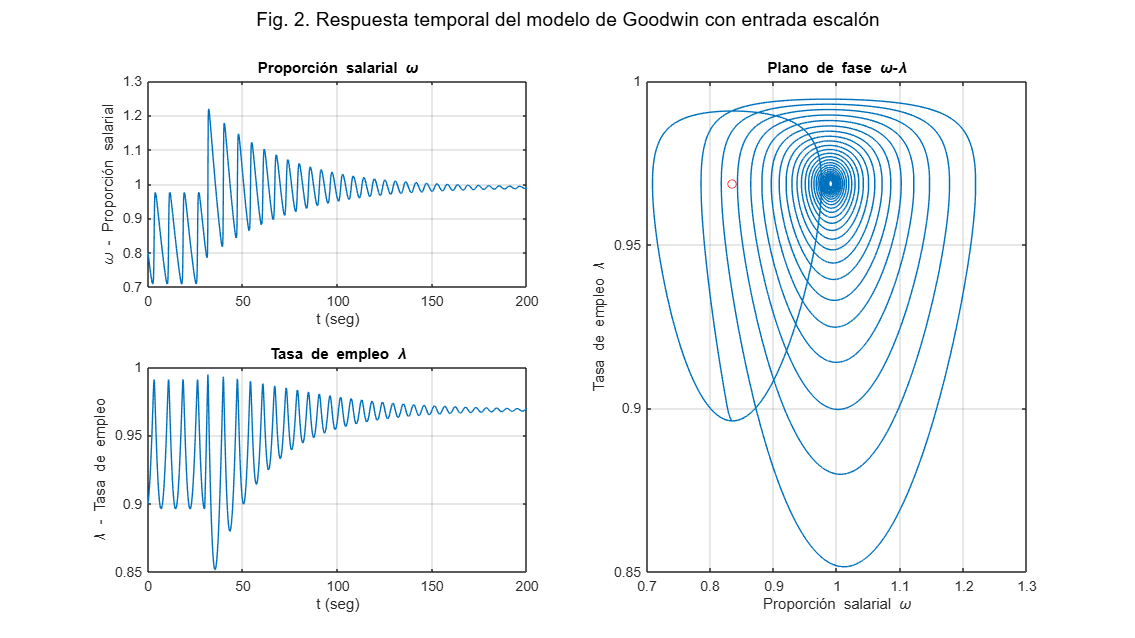

% Escalón
nu = 3;              % razón capital-producto
alpha = 0.025;       % tasa de crecimiento de la productividad
beta = 0.02;         % tasa de crecimiento de la población
delta = 0.01;        % tasa de depreciación
phi0 = 0.04/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega
x20 = 0.9; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial

tmax = 200;
t = linspace(0, tmax, 1000)'; % Vector de tiempo con 1000 puntos entre 0 y tmax
u_step = zeros(size(t));
u_step(t >= 30) = 0.05; % Escalón que inicia en t=30

% Crear la señal de entrada para "From Workspace"
u_input = [t u_step];

% Ejecutar la simulación
sim('goodwin')

% Extraer datos y graficar resultados
t = x.time;
x1 = x.signals.values(:,1); % w = x1 (Proporción salarial)
x2 = x.signals.values(:,2); % lambda = x2 (Razón de empleo)
x3 = x.signals.values(:,3); % Y_output = x3 (Producto Interno Bruto (GDP))

figure('Units','normalized','Position',[0 0 1 1])
sgtitle({'Fig. 2. Respuesta temporal del modelo de Goodwin con entrada escalón';''})

% Gráfica de Proporción Salarial
subplot(2,2,1)
plot(t,x1)
xlabel('t (seg)'), ylabel('\omega - Proporción salarial'), title('Proporción salarial \omega'), grid

% Gráfica de Tasa de Empleo
subplot(2,2,3)
plot(t,x2)
xlabel('t (seg)'), ylabel('\lambda - Tasa de empleo'), title('Tasa de empleo \lambda'), grid

% Diagrama de fase
subplot(2,2,[2,4])
plot(x1,x2); hold on;
plot(omega_bar, lambda_bar, 'ro')
xlabel('Proporción salarial \omega'), ylabel('Tasa de empleo \lambda'), title('Plano de fase \omega-\lambda'), grid

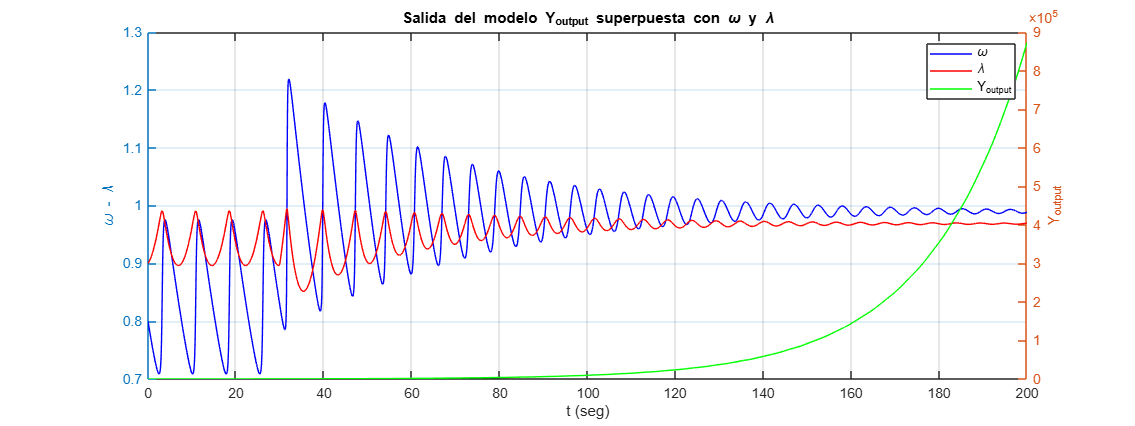

% Crear la figura
figure('Units','normalized','Position',[0 0 0.9 0.6])

% Eje izquierdo para x1 y x2
yyaxis left
plot(t, x1, '-b', 'DisplayName', '\omega'); % Gráfica de x1
hold on
plot(t, x2, '-r', 'DisplayName', '\lambda'); % Gráfica de x2
xlabel('t (seg)');
ylabel('\omega - \lambda');
title('Salida del modelo Y_{output} superpuesta con \omega y \lambda');
grid on
legend('show');

% Eje derecho para x3
yyaxis right
plot(t, x3, '-g', 'DisplayName', 'Y_{output}'); % Gráfica de x3
ylabel('Y_{output}');

### 3.4. Simulación con una entrada tipo sinusoidal

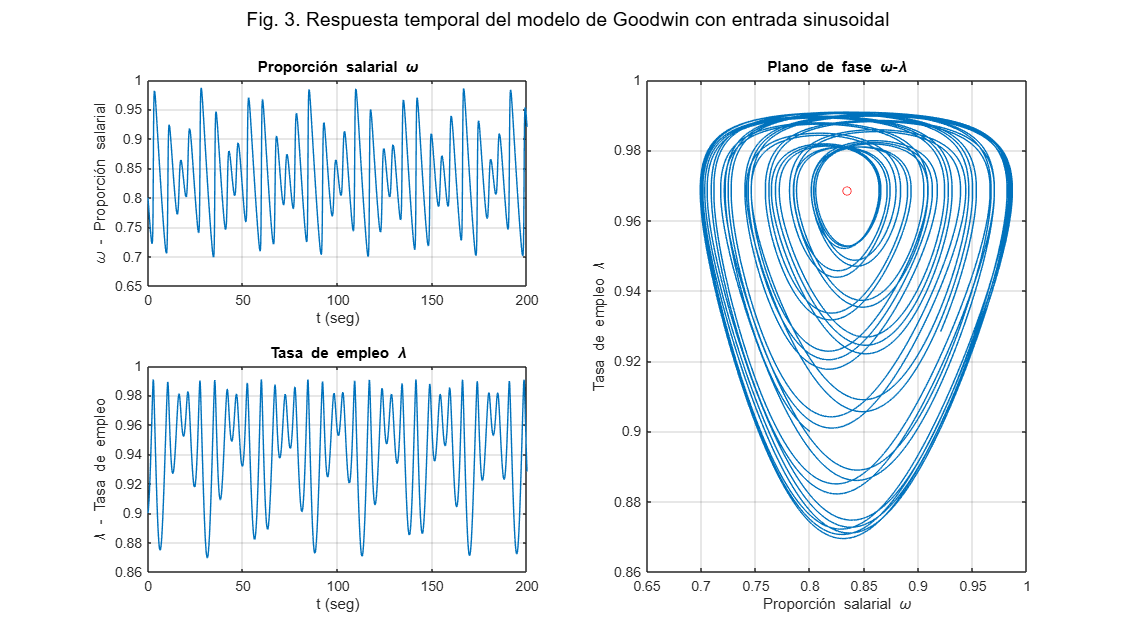

% Sinusoidal
nu = 3;              % razón capital-producto
alpha = 0.025;       % tasa de crecimiento de la productividad
beta = 0.02;         % tasa de crecimiento de la población
delta = 0.01;        % tasa de depreciación
phi0 = 0.04/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega
x20 = 0.9; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial

tmax = 200;
t = linspace(0, tmax, 1000)'; % Vector de tiempo con 1000 puntos entre 0 y tmax
u = 0.01*sin(t); % Señal de entrada

% Crear la señal de entrada para "From Workspace"
u_input = [t u];

% Ejecutar la simulación
sim('goodwin')

fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2);  % inversa de la curva de Phillips
omega_bar =  1-nu*(alpha+beta+delta);           % equilibrio proporción salarial
lambda_bar = fun_Phi_inv(alpha);                % equilibrio razón de empleo

% Extraer datos y graficar resultados
t = x.time;
x1 = x.signals.values(:,1); % w = x1 (Proporción salarial)
x2 = x.signals.values(:,2); % lambda = x2 (Razón de empleo)
x3 = x.signals.values(:,3); % Y_output = x3 (Producto Interno Bruto (GDP))

figure('Units','normalized','Position',[0 0 1 1])
sgtitle({'Fig. 3. Respuesta temporal del modelo de Goodwin con entrada sinusoidal';''})

% Gráfica de Proporción Salarial
subplot(2,2,1)
plot(t,x1)
xlabel('t (seg)'), ylabel('\omega - Proporción salarial'), title('Proporción salarial \omega'), grid

% Gráfica de Tasa de Empleo
subplot(2,2,3)
plot(t,x2)
xlabel('t (seg)'), ylabel('\lambda - Tasa de empleo'), title('Tasa de empleo \lambda'), grid

% Diagrama de fase
subplot(2,2,[2,4])
plot(x1,x2); hold on;
plot(omega_bar, lambda_bar, 'ro')
xlabel('Proporción salarial \omega'), ylabel('Tasa de empleo \lambda'), title('Plano de fase \omega-\lambda'), grid

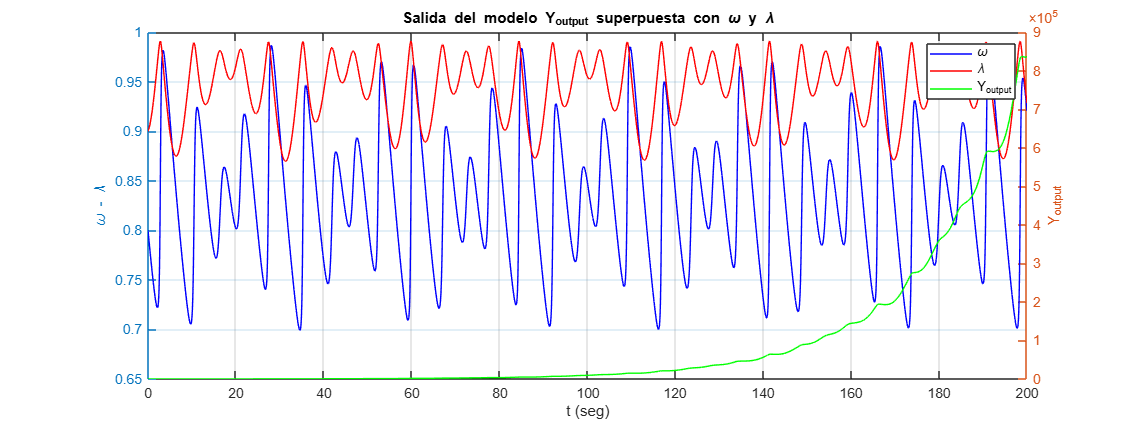

% Crear la figura
figure('Units','normalized','Position',[0 0 0.9 0.6])

% Eje izquierdo para x1 y x2
yyaxis left
plot(t, x1, '-b', 'DisplayName', '\omega'); % Gráfica de x1
hold on
plot(t, x2, '-r', 'DisplayName', '\lambda'); % Gráfica de x2
xlabel('t (seg)');
ylabel('\omega - \lambda');
title('Salida del modelo Y_{output} superpuesta con \omega y \lambda');
grid on
legend('show');

% Eje derecho para x3
yyaxis right
plot(t, x3, '-g', 'DisplayName', 'Y_{output}'); % Gráfica de x3
ylabel('Y_{output}');

### 3.5. Simulación con una entrada tipo pulso

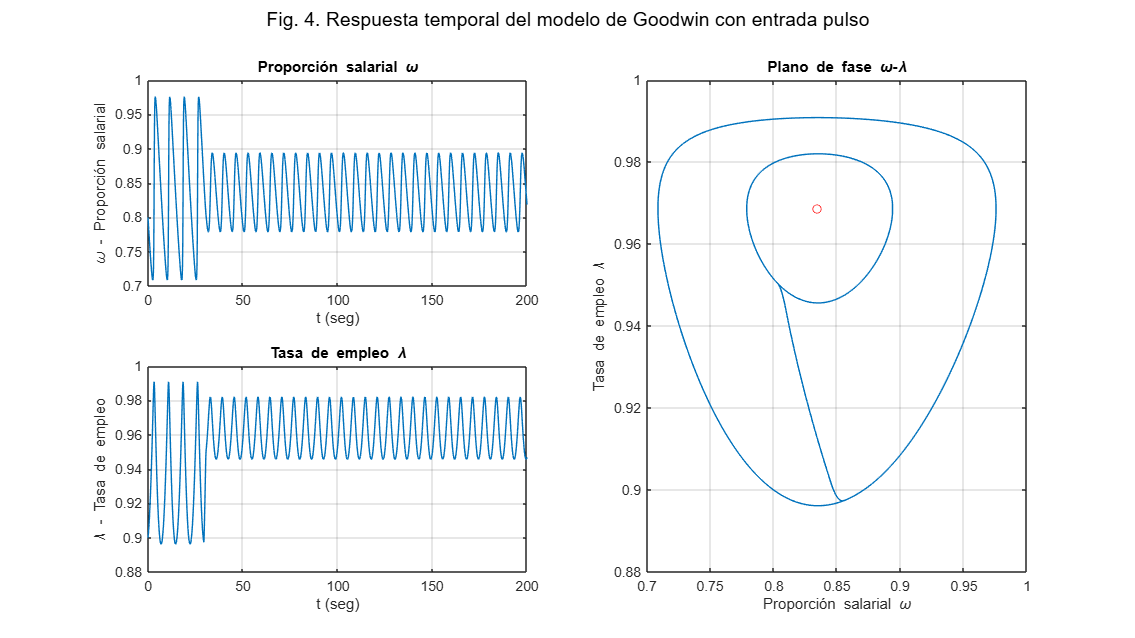

% Pulso
nu = 3;              % razón capital-producto
alpha = 0.025;       % tasa de crecimiento de la productividad
beta = 0.02;         % tasa de crecimiento de la población
delta = 0.01;        % tasa de depreciación
phi0 = 0.04/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega
x20 = 0.9; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial

tmax = 200;
t = linspace(0, tmax, 1000)'; % Vector de tiempo con 1000 puntos entre 0 y tmax
u = zeros(size(t)); % Inicializa la señal de entrada en cero
u(t >= 29.5 & t <= 30.5) = 0.05; % Define el pulso en aprox t=30

% Crear la señal de entrada para "From Workspace"
u_input = [t u];

% Ejecutar la simulación
sim('goodwin')

fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2);  % inversa de la curva de Phillips
omega_bar =  1-nu*(alpha+beta+delta);           % equilibrio proporción salarial
lambda_bar = fun_Phi_inv(alpha);                % equilibrio razón de empleo

% Extraer datos y graficar resultados
t = x.time;
x1 = x.signals.values(:,1); % w = x1 (Proporción salarial)
x2 = x.signals.values(:,2); % lambda = x2 (Razón de empleo)
x3 = x.signals.values(:,3); % Y_output = x3 (Producto Interno Bruto (GDP))

figure('Units','normalized','Position',[0 0 1 1])
sgtitle({'Fig. 4. Respuesta temporal del modelo de Goodwin con entrada pulso';''})

% Gráfica de Proporción Salarial
subplot(2,2,1)
plot(t,x1)
xlabel('t (seg)'), ylabel('\omega - Proporción salarial'), title('Proporción salarial \omega'), grid

% Gráfica de Tasa de Empleo
subplot(2,2,3)
plot(t,x2)
xlabel('t (seg)'), ylabel('\lambda - Tasa de empleo'), title('Tasa de empleo \lambda'), grid

% Diagrama de fase
subplot(2,2,[2,4])
plot(x1,x2); hold on;
plot(omega_bar, lambda_bar, 'ro')
xlabel('Proporción salarial \omega'), ylabel('Tasa de empleo \lambda'), title('Plano de fase \omega-\lambda'), grid

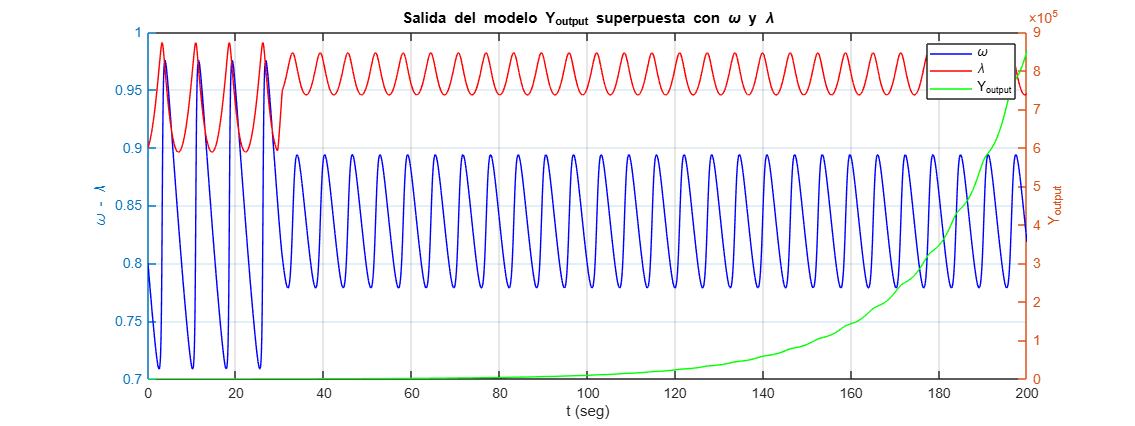

% Crear la figura
figure('Units','normalized','Position',[0 0 0.9 0.6])

% Eje izquierdo para x1 y x2
yyaxis left
plot(t, x1, '-b', 'DisplayName', '\omega'); % Gráfica de x1
hold on
plot(t, x2, '-r', 'DisplayName', '\lambda'); % Gráfica de x2
xlabel('t (seg)');
ylabel('\omega - \lambda');
title('Salida del modelo Y_{output} superpuesta con \omega y \lambda');
grid on
legend('show');

% Eje derecho para x3
yyaxis right
plot(t, x3, '-g', 'DisplayName', 'Y_{output}'); % Gráfica de x3
ylabel('Y_{output}');

### 3.6. Variación del parámetro alpha $\alpha$

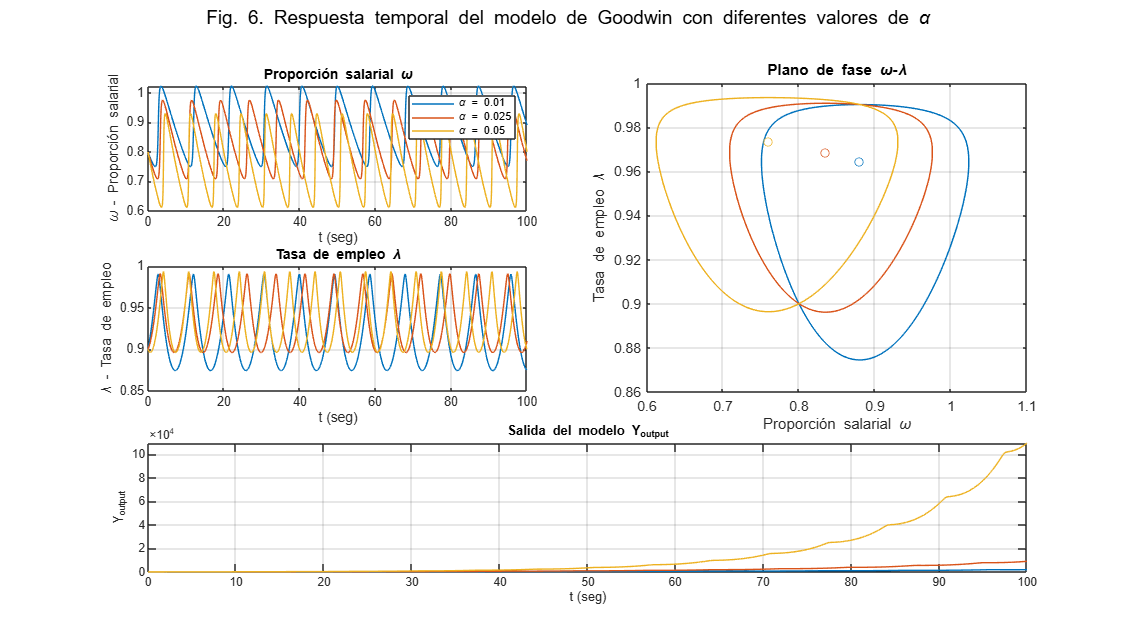

% Variación del parámetro alpha del modelo de Goodwin
nu = 3;              % razón capital-producto
beta = 0.02;         % Tasa de crecimiento de la población
delta = 0.01;        % Tasa de depreciación
phi0 = 0.04/(1-0.04^2); % Parámetro de la curva de Phillips,  Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % Parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega (Proporción salarial)
x20 = 0.9; % Condiciones iniciales para lambda (tasa de empleo)
y0 = 100;   % PIB inicial

tmax = 100;  % Tiempo máximo de simulación
t = linspace(0, tmax, 1000)'; % Vector de tiempo con 1000 puntos entre 0 y tmax
u = zeros(size(t)); % Señal constante igual a 0 para todos los puntos de tiempo

% Crear la señal de entrada para From Workspace
u_input = [t u];

% Valores del parámetro alpha (Tasa de crecimiento de la productividad) que varía
alpha_values = [0.01 0.025 0.05];  % Diferentes valores de alpha
N = length(alpha_values);

% Preparar la figura
figure('Units', 'normalized', 'Position', [0 0 1 1])
leyenda = cell(1, N);  % Inicializar la leyenda

% Obtener los colores predeterminados del gráfico
colores = get(gca, 'ColorOrder');

% Bucle sobre los diferentes valores de alpha
for i = 1:N
    alpha = alpha_values(i);  % Cambiar el valor de alpha
    sim('goodwin')      % Ejecutar la simulación con el valor de alpha actual

    % Extraer los resultados de la simulación
    t_sim = x.time;
    w_sim = x.signals.values(:,1); % w = Proporción salarial
    lambda_sim = x.signals.values(:,2); % lambda = Razón de empleo
    Y_output_sim = x.signals.values(:,3); % Producto Interno Bruto (GDP)

    % Graficar resultados
    subplot(3,2,1)
    plot(t_sim, w_sim, 'Color', colores(i,:)) % Usar el color correspondiente
    hold on
    xlabel('t (seg)'), ylabel('\omega - Proporción salarial'), title('Proporción salarial \omega'), grid

    subplot(3,2,3)
    plot(t_sim, lambda_sim, 'Color', colores(i,:)) % Usar el color correspondiente
    hold on
    xlabel('t (seg)'), ylabel('\lambda - Tasa de empleo'), title('Tasa de empleo \lambda'), grid
    
    fun_Phi_inv = @(x) 1 - (phi1/(x + phi0)).^(1/2);
    omega_bar = 1 - nu * (alpha + beta + delta);
    lambda_bar = fun_Phi_inv(alpha);

    subplot(3,2,[2,4])
    plot(w_sim, lambda_sim, 'Color', colores(i,:)); hold on; % Usar el color correspondiente
    plot(omega_bar, lambda_bar, 'o', 'Color', colores(i,:)) % Usar el color correspondiente para el punto de equilibrio
    xlabel('Proporción salarial \omega'), ylabel('Tasa de empleo \lambda'), title('Plano de fase \omega-\lambda'), grid

    % Graficar Y_output
    subplot(3,2,[5,6])
    plot(t_sim, Y_output_sim, 'Color', colores(i,:)) % Usar el color correspondiente
    hold on
    xlabel('t (seg)'), ylabel('Y_{output}'), title('Salida del modelo Y_{output}'), grid

    leyenda{i} = ['\alpha = ' num2str(alpha)];
end

% Agregar leyenda y título general a las primeras gráficas
subplot(3,2,1)
legend(leyenda)
sgtitle({'Fig. 6. Respuesta temporal del modelo de Goodwin con diferentes valores de \alpha';''})

alpha_values = [0.01, 0.025, 0.05];

% Calculo de los equilibrios para cada alpha
for alpha = alpha_values

    fun_Phi_inv = @(x) 1 - (phi1/(x + phi0)).^(1/2);
    omega_bar = 1 - nu * (alpha + beta + delta);
    lambda_bar = fun_Phi_inv(alpha);
    
    fprintf('Para alpha = %.3f: omega_bar = %.4f, lambda_bar = %.4f\n', alpha, omega_bar, lambda_bar);
end

Para alpha = 0.010: omega_bar = 0.8800, lambda_bar = 0.9642
Para alpha = 0.025: omega_bar = 0.8350, lambda_bar = 0.9686
Para alpha = 0.050: omega_bar = 0.7600, lambda_bar = 0.9733


Veamos cómo cambia la respuesta temporal para diferentes valores en el parámetro $\alpha$

### 3.7. Variación del parámetro delta $\delta$

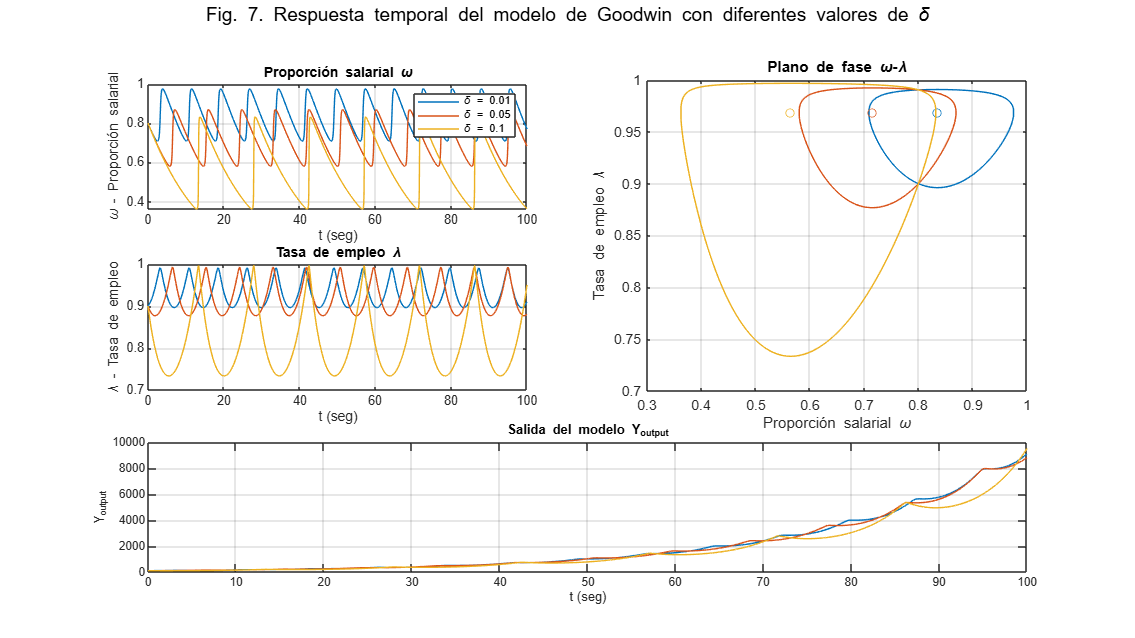

% Variación del parámetro delta del modelo de Goodwin
nu = 3;              % razón capital-producto
alpha = 0.025;       % Tasa de crecimiento de la productividad
beta = 0.02;         % Tasa de crecimiento de la población
phi0 = 0.04/(1-0.04^2); % Parámetro de la curva de Phillips,  Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % Parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega (Proporción salarial)
x20 = 0.9; % Condiciones iniciales para lambda (tasa de empleo)
y0 = 100;   % PIB inicial

tmax = 100;  % Tiempo máximo de simulación
t = linspace(0, tmax, 1000)'; % Vector de tiempo con 1000 puntos entre 0 y tmax
u = zeros(size(t)); % Señal constante igual a 0 para todos los puntos de tiempo

% Crear la señal de entrada para From Workspace
u_input = [t u];

% Valores del parámetro delta (tasa de depreciación) que varía
delta_values = [0.01 0.05 0.1];  % Diferentes valores de delta
N = length(delta_values);

% Preparar la figura
figure('Units', 'normalized', 'Position', [0 0 1 1])
leyenda = cell(1, N);  % Inicializar la leyenda

% Obtener los colores predeterminados del gráfico
colores = get(gca, 'ColorOrder');

% Bucle sobre los diferentes valores de delta
for i = 1:N
    delta = delta_values(i);  % Cambiar el valor de delta
    sim('goodwin')            % Ejecutar la simulación con el valor de delta actual

    % Extraer los resultados de la simulación
    t_sim = x.time;
    w_sim = x.signals.values(:,1); % w = Proporción salarial
    lambda_sim = x.signals.values(:,2); % lambda = Razón de empleo
    Y_output_sim = x.signals.values(:,3); % Producto Interno Bruto (GDP)

    % Graficar resultados
    subplot(3,2,1)
    plot(t_sim, w_sim, 'Color', colores(i,:))
    hold on
    xlabel('t (seg)'), ylabel('\omega - Proporción salarial'), title('Proporción salarial \omega'), grid

    subplot(3,2,3)
    plot(t_sim, lambda_sim, 'Color', colores(i,:))
    hold on
    xlabel('t (seg)'), ylabel('\lambda - Tasa de empleo'), title('Tasa de empleo \lambda'), grid

    fun_Phi_inv = @(x) 1 - (phi1/(x + phi0)).^(1/2);
    omega_bar = 1 - nu * (alpha + beta + delta);
    lambda_bar = fun_Phi_inv(alpha);

    subplot(3,2,[2,4])
    plot(w_sim, lambda_sim, 'Color', colores(i,:)); hold on;
    plot(omega_bar, lambda_bar, 'o', 'Color', colores(i,:)) % Usar el color correspondiente para el punto de equilibrio
    xlabel('Proporción salarial \omega'), ylabel('Tasa de empleo \lambda'), title('Plano de fase \omega-\lambda'), grid

    % Graficar Y_output
    subplot(3,2,[5,6])
    plot(t_sim, Y_output_sim, 'Color', colores(i,:))
    hold on
    xlabel('t (seg)'), ylabel('Y_{output}'), title('Salida del modelo Y_{output}'), grid

    leyenda{i} = ['\delta = ' num2str(delta)];
end

% Agregar leyenda y título general a las primeras gráficas
subplot(3,2,1)
legend(leyenda)
sgtitle({'Fig. 7. Respuesta temporal del modelo de Goodwin con diferentes valores de \delta';''})

delta_values = [0.01 0.05 0.1];

% Calculo de los equilibrios para cada alpha
for delta = delta_values

    fun_Phi_inv = @(x) 1 - (phi1/(x + phi0)).^(1/2);
    omega_bar = 1 - nu * (alpha + beta + delta);
    lambda_bar = fun_Phi_inv(alpha);
    
    fprintf('Para delta = %.3f: omega_bar = %.4f, lambda_bar = %.4f\n', delta, omega_bar, lambda_bar);
end

Para delta = 0.010: omega_bar = 0.8350, lambda_bar = 0.9686
Para delta = 0.050: omega_bar = 0.7150, lambda_bar = 0.9686
Para delta = 0.100: omega_bar = 0.5650, lambda_bar = 0.9686


Veamos cómo cambia la respuesta temporal para diferentes valores en el parámetro $\delta$

## 4. Discusión

### 4.1. Limitaciones del modelo

El modelo de Goodwin, en su formulación original, no incluye mecanismos que aseguren que las variables clave, como la proporción salarial ($\omega$) y la tasa de empleo ($\lambda$), se mantengan dentro de límites económicamente razonables, es decir, dentro del intervalo [0, 1]. Esto puede generar resultados teóricamente inconsistentes, como valores de $\omega$ superiores a 1, lo que implicaría que los salarios exceden el producto total de la economía, algo que carece de sentido desde una perspectiva económica. Una posible solución sería incorporar restricciones adicionales que impongan límites a las variables, garantizando que las simulaciones reflejen comportamientos más consistentes con la realidad económica. Esta modificación podría mejorar la precisión y utilidad del modelo al aplicarlo en contextos prácticos.

### **4.2. Efecto de una entrada tipo escalón**

En esta simulación, se introduce un incremento de 0.05 en el tiempo 30, la salida del modelo aumentó ligeramente a 9660 en comparación con el valor de 9101 en el modelo original sin perturbación. La tasa de empleo ($\lambda$) y la proporción salarial ($\omega$) dejaron de oscilar, convergiendo hacia valores estables. Mientras que la tasa de empleo se mantuvo en 0.96, la proporción salarial aumentó a 0.99. Económicamente, esto sugiere que la inyección de un estímulo fijo en el sistema estabiliza la dinámica laboral, manteniendo la tasa de empleo constante pero elevando la proporción del ingreso destinado a los salarios. Es decir, un aumento en la entrada externa fomenta una mayor redistribución de la riqueza hacia los trabajadores sin afectar la estabilidad del empleo. Sin embargo, la estabilidad a largo plazo en un nivel tan alto de proporción salarial (0.99) podría no ser sostenible en una economía real, ya que dejaría poco margen para la inversión y el crecimiento del capital.

### **4.3. Efecto de una entrada tipo sinusoidal**

Se observa que la tasa de empleo y la proporción salarial presentan un comportamiento ondulante, acorde con la naturaleza de la entrada sinusoidal de 0.01*sin(t). Aunque se mantienen en un ciclo oscilatorio, el sistema sigue convergiendo hacia el mismo punto de equilibrio. La salida también mostró un leve incremento a 9550. Económicamente, este resultado sugiere que las fluctuaciones en la entrada reflejan una mayor variabilidad en la distribución salarial y el empleo, pero el sistema tiende a regresar a su estado de equilibrio. Este tipo de entrada podría modelar situaciones donde la productividad o la inversión tienen variaciones cíclicas en lugar de un cambio fijo, afectando temporalmente la dinámica de distribución, pero sin alterarla a largo plazo. La capacidad del sistema para absorber estas fluctuaciones sin desestabilizarse completamente indica una cierta resiliencia en el modelo económico.

### **4.4. Efecto de una entrada tipo pulso**

En esta simulación con una entrada de 0.05 y duración muy corta entre 29.5 y 30.5, se observó que la amplitud de las oscilaciones en la tasa de empleo y la proporción salarial disminuyó, aunque el punto de equilibrio se mantuvo intacto. La salida fue de 9525, también ligeramente superior al modelo orginal. Este comportamiento podría representar el impacto de eventos económicos puntuales, como crisis financieras breves o cambios repentinos en políticas económicas. Económicamente, una perturbación breve en el sistema podría representar un evento puntual que afecta temporalmente la distribución y el empleo, pero sin modificar sustancialmente la dinámica general del modelo económico. El mantenimiento del punto de equilibrio indica que la estructura fundamental de la economía (en términos de distribución del ingreso y empleo) puede ser resistente a perturbaciones breves.

### **4.5. Efecto del parámetro **$\alpha$** (Tasa de crecimiento de la productividad)**

La variación en el parámetro de la tasa de crecimiento de la productividad en el modelo de Goodwin muestra un impacto significativo en la proporción salarial ($\omega$) y en la producción total, además de un impacto bajo en la tasa de empleo ($\lambda$). Con un $\alpha$ bajo de 0.010, la producción total es de 1952, y la proporción salarial se sitúa en 0.880, lo que indica que los salarios aún representan una parte considerable de la economía. Cuando $\alpha$ aumenta a 0.025, la producción se incrementa a 9101; sin embargo, la proporción salarial disminuye a 0.835, sugiriendo que el crecimiento en la producción no se traduce en un aumento equitativo de los salarios. Finalmente, al alcanzar un $\alpha$ alto de 0.050, la producción se eleva drásticamente a 109672, pero la proporción salarial cae aún más a 0.760. Este resultado sugiere que el crecimiento de la productividad, aunque beneficioso para la producción total, puede no traducirse en beneficios proporcionales para los trabajadores. La disminución de la proporción salarial a medida que aumenta la productividad podría indicar una creciente desigualdad económica, un fenómeno observado en muchas economías. El leve aumento en la tasa de empleo contradice parcialmente nuestra hipótesis inicial, sugiriendo que el crecimiento de la productividad puede tener un impacto menor en el empleo de lo esperado.

### **4.6. Efecto del parámetro **$\delta$** (Tasa de depreciación)**

La variación en el parámetro de la tasa de depreciación del modelo de Goodwin muestra un efecto notable en la proporción salarial ($\omega$), mientras que la tasa de empleo ($\lambda$) se mantiene constante en 0.968. Al aumentar delta de 0.01 a 0.05 y a 0.10, la salida del modelo no varia mucho, presentando valores de 9101, 8806 y 9505, respectivamente. A la vez, la proporción salarial $\omega$ disminuyen: 0.835 para delta = 0.01, 0.715 para delta = 0.05, y 0.565 para delta = 0.10. La disminución de la proporción salarial con el aumento de la depreciación sugiere que los costos de mantenimiento y reemplazo del capital pueden ser trasladados a los trabajadores en forma de salarios más bajos. La estabilidad de la tasa de empleo indica que el mercado laboral puede ser más resiliente a los cambios en la tasa de depreciación de lo que se pensaba inicialmente. Este resultado desafía parcialmente nuestra hipótesis inicial sobre el impacto de la depreciación en el empleo, sugiriendo que otros factores pueden compensar el potencial efecto negativo de una mayor depreciación en la inversión y el empleo.

### **4.7. Conclusiones generales**

Este estudio ha ofrecido nuevas perspectivas sobre la dinámica del modelo de Goodwin y su relevancia en los ciclos económicos y la distribución del ingreso. Los resultados destacan la complejidad de las interacciones entre productividad, empleo y salarios, desafiando suposiciones simplistas sobre el crecimiento económico. A pesar de sus limitaciones, el modelo sigue siendo útil para el análisis conceptual de la dinámica económica, y las modificaciones implementadas en este trabajo han revelado mecanismos adicionales que influyen en los ciclos económicos. Además, este estudio permite ver la necesidad de un enfoque más amplio en el análisis económico, que considere tanto factores internos como externos para mejorar la formulación de políticas.

## 5. Referencias

[1] Vélez S., C. M. (2024). *Sistemas dinámicos en contexto: Modelación matemática, simulación, estimación y control con MATLAB*.

[2] Grasselli, M.R., Costa Lima, B. An analysis of the Keen model for credit expansion, asset price bubbles and financial fragility. *Math Finan Econ* **6**, 191–210 (2012). https://doi.org/10.1007/s11579-012-0071-8

[3] Grasselli, M. R. *The Goodwin Model*. McMaster University. [https://ms.mcmaster.ca/~grasselli/goodwin.html](https://ms.mcmaster.ca/~grasselli/goodwin.html)

[4] Almeida, Mafalda Oliveira Martins Bastos de (2017). "The Lotka-Volterra equations in finance and economics". Dissertação de Mestrado, Universidade de Lisboa. Instituto Superior de Economia e Gestão.

[5] Mahmud, Sri & Resmawan, Resmawan & Ismail, Sumarno & Nurwan, Nurwan & Taki, Febriani. (2022). Goodwin Model with Clustering Workers' Skills in Indonesian Economic Cycle. CAUCHY. 7. 249-266. 10.18860/ca.v7i2.13458. 

[6] Wikipedia contributors. (2023) *Goodwin model (economics)*. Wikipedia. [https://en.wikipedia.org/wiki/Goodwin_model_(economics)](https://en.wikipedia.org/wiki/Goodwin_model_(economics))

[7] MathWorks. *Simulink*. [https://la.mathworks.com/help/simulink/](https://la.mathworks.com/help/simulink/)